# Optimize Gear Ratios for Vehicle Launch

Copyright 2026 The MathWorks, Inc.

## Overview

The vehicle launch maneuver for an electric vehicle requires higher torque for performance at the same time high torque may cause a jerky launch experience. This work flow optimizes the launch performance by minimizing the jerk during launch maneuver of an electric vehicle. 

## Specify Required Launch Performance

You specify the launch performance in terms of time range required to attain a vehicle speed of 0-60 mph. Use function `calculateAcceleration.m` to estimate the required acceleration profile for the vehicle.

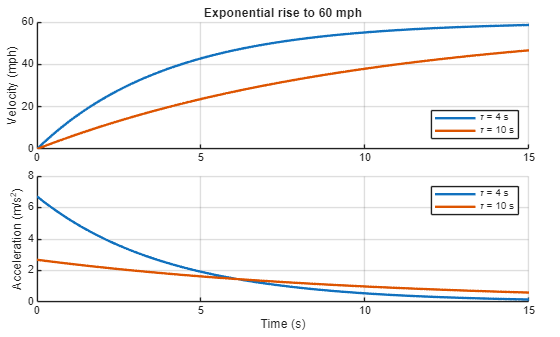

launchTimeVector = simscape.Value(linspace(0,15,300),"s");
velocityTimeConstant = simscape.Value([4,10],"s");
[velocityProfile,accelerationProfile] = generateVelocityProfile(launchTimeVector.value,velocityTimeConstant.value);

Specify vehicle parameters.

vehicleMass = simscape.Value(1000,"kg");
frontalArea = simscape.Value(2.15,"m^2");
tyreRoadRollingFriction = 0.0075;
airDragCoefficient = 0.25;
tireRadius = simscape.Value(0.35,"m");
overallGgearRatio = 9;

Calculate the traction force required at tire to meet the required vehicle acceleration.

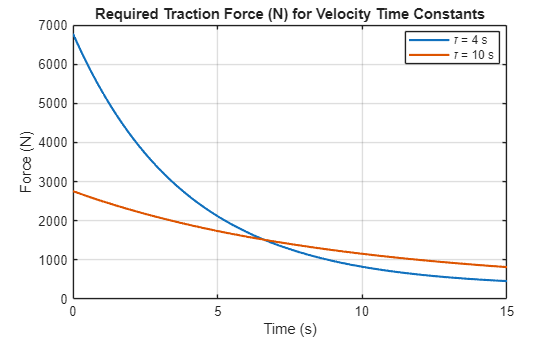

FTraction = simscape.Value(calculateTractionForceMatrix(accelerationProfile,velocityProfile,vehicleMass.value,...
   tyreRoadRollingFriction,airDragCoefficient,frontalArea.value,launchTimeVector.value,velocityTimeConstant.value),"N");

## Estimate Motor Torque

For the the estimated traction force required at wheel the motor should generate a suitable torque. The required motor torque depends on the overall gear ratio and the tire radius. 

meanTorqueVectorHigh = simscape.Value(mean(FTraction(:,1).value),"N")*(tireRadius)/overallGgearRatio;
meanTorqueVectorLow = simscape.Value(mean(FTraction(:,2).value),"N")*(tireRadius)/overallGgearRatio;
VehicleLaunchTorqueVect = simscape.Value(ceil(linspace(min(meanTorqueVectorLow.value),max(meanTorqueVectorHigh.value),3)),"N*m")

VehicleLaunchTorqueVect =     60    69    77

    (N*m)


  Use precalculated motor torque saved in MAT file `extendedVehicleLaunchTorque`.  For a different motor, generate the motor torque profiles by running the sample script.

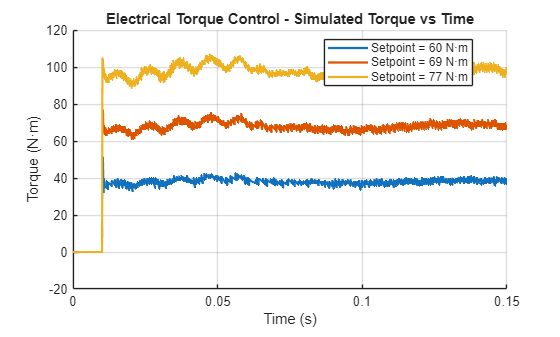

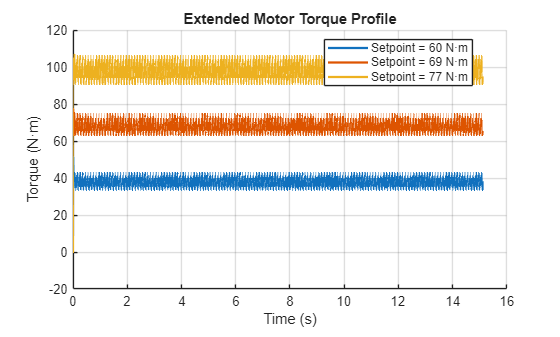

inputData = load("extendedVehicleLaunchTorque.mat");
plotExtendedTorque(VehicleLaunchTorqueVect,inputData);

## Optimize the Vehicle Launch Performance

The PMSM motor generates the torque required to accelerate the vehicle. Torque ripple arising due to inverter switching is responsible for exiting torsional vibrations in the drive line. When the motor is integrated with a flexible driveline the driveline components play a role to damp the vibrations. Use this section of the workflow to minimize the RMS of jerk experienced by the vehicle while maximizing the average acceleration during the launch. The function runs a surrogate optimization to optimize gear ratios. The surrogate optimizer simulates the simscape model `mechanicalDLTorsionOrderMap` to generate random response. The simscape model reads the dynamic torque produced by the electric motor that you saved in the MAT file `extendedVehicleLaunchTorque` via a workspace variable named TRQTime.

- Between motor shaft and the transmission main shaft.

- Between Transmission main shaft and the output shaft.

- Between the output shaft to differential ring gear (final drive).

Specify inputs for the surrogate optimization.

modelName = "mechanicalDLTorsionOrderMap";
outputBlockPath = "mechanicalDLTorsionOrderMap/Vehicle Dynamics"; % block path to the outport producing the output
outputSignalName = "F"; % output signal name in the model
% input torque levels
timeData = inputData.timeCell;
trqData = inputData.EXTtorqueCell;
scenarioLevels = struct("Name", {"Low","Mid","High"}, ...
    "Value",{[timeData{1} trqData{1}], [timeData{2} trqData{2}], [timeData{3} trqData{3}]});
baseLine = [2.5 1.01 3]; % base line design gear ratio

Set maximum jerk measurement sample frequency relevant for passenger comfort.

sampleFrequency = simscape.Value(100,"Hz");

Run multilevel surrogate optimization. Optionally specify `ObjectiveWeights` to minimize jerk and maximize the vehicle acceleration.

Signal logging enabled on "mechanicalDLTorsionOrderMap/Vehicle Dynamics" with name "F".


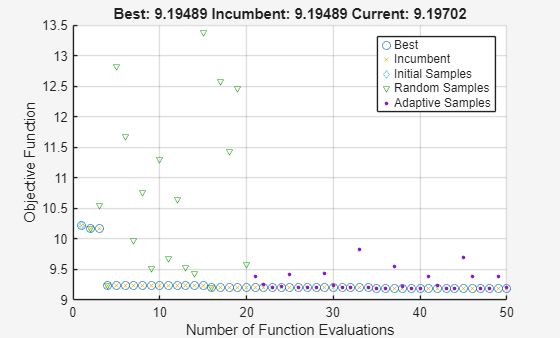


=== Surrogate optimization complete ===
                                    Optimized Gear Ratio
                                    ____________________

    Motor Shaft to Counter Shaft              1.5       
    Counter Shaft to Main Shaft            1.5756       
    Final Drive Ratio                       2.008       

Composite objective (jerk w=0.70

    optGearRatios = runMultiLevelSurrogateOptimisation(modelName,outputBlockPath,...
        outputSignalName,SimulationTime=simscape.Value(2,"s"),ScenarioLevels=scenarioLevels,...
        LowerBound=[1.5 1,2],UpperBound=[2.5,1.75,4],InitialPoints=baseLine,MaximumSimulations=50,ObjectiveWeights=[0.7, 0.3],FixedTimeStep=1/value(sampleFrequency));

## Simulate Optimized Vehicle Launch

Verify the vehicle launch at middle torque level.

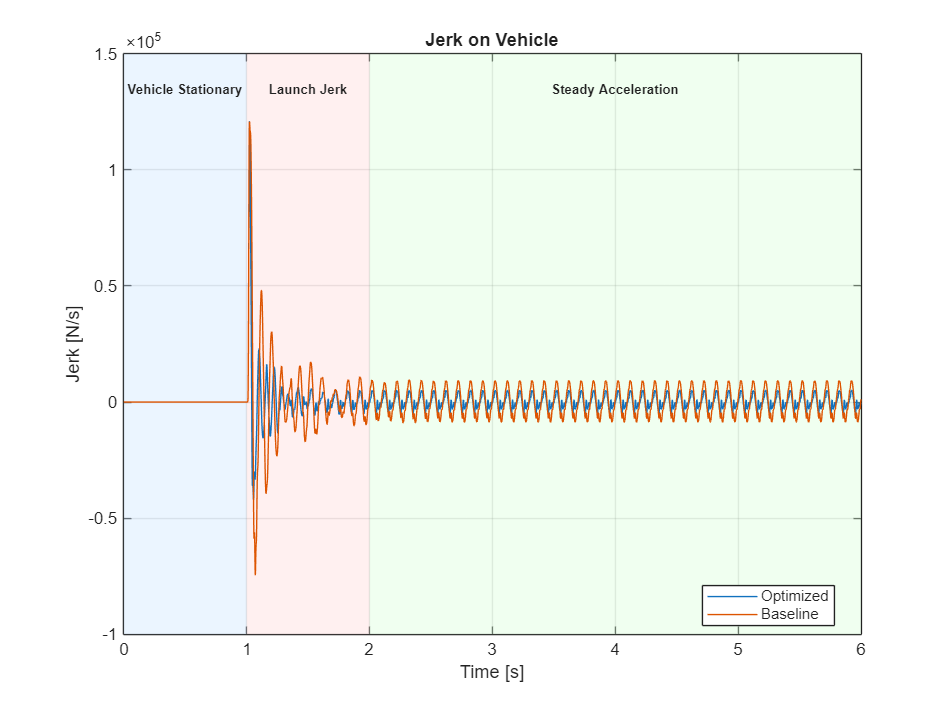

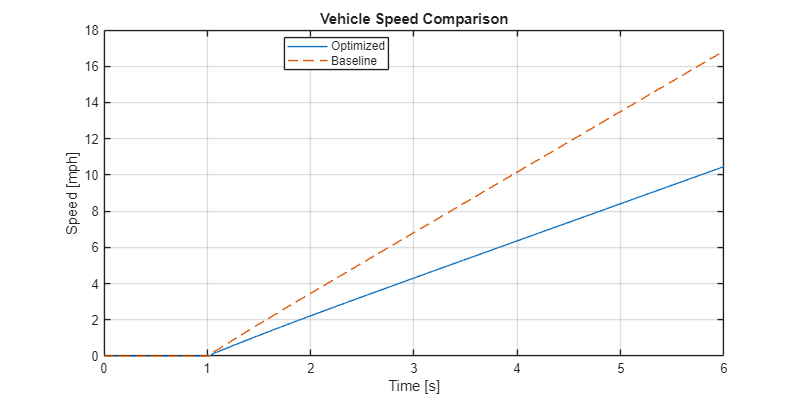

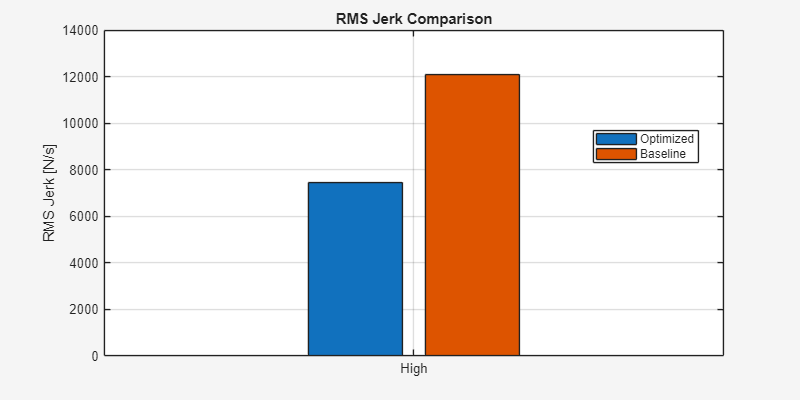

simulateOptlaunch(modelName, outputSignalName,BaseXY=baseLine,BestXY=optGearRatios,ScenarioLevels=scenarioLevels(3),StopTime=simscape.Value(5,"s"));

  The optimized gear ratios provide significant improvement in ride comfort during vehicle launch at a smaller cost of launch acceleration performance.  

##  Clear Work Space

clear("timeData","trqData","inputData");